clear;clc;

## Simulation setup

Ain=sqrt(0.5); % Signal amplitude
Ts=1/5.12e6; % Sampling interval (s)
N=65536; % Number of FFT points
Fin=31/N/Ts; % Signal frequency (Hz)


## Run simulation

[input,bitstream,output] = simDeltaSigmaAdc(Ts,Fin,Ain,N);

% Normalize output amplitude to match with Input
output.("Voltage (V)") = 2^(-21)*output.("Voltage (V)");


## Plot waveforms

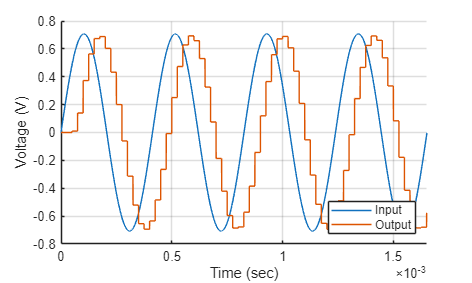

fig = figure('Units','inches','Position',[0 0 5 3]);
fontname(fig,'TeXGyreTermes');
fontsize(fig,10,"points");

% Input vs Output Signal
t_max = 4/Fin;
t_max_index = floor(t_max/Ts);

hold on;
plot(input(1:t_max_index,:),"Time (sec)","Voltage (V)");
plot(output(1:t_max_index,:),"Time (sec)","Voltage (V)");
hold off;
xlim([0,t_max]);
legend(["Input", "Output"],"Location","southeast");
grid on;

exportgraphics(fig,"figures/waveform_input_vs_output_ideal.svg");

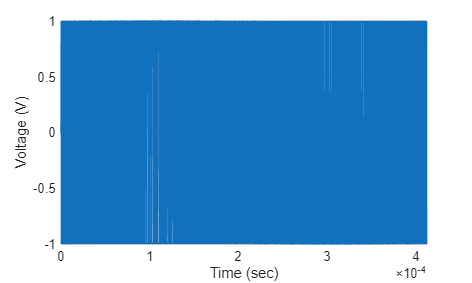


% Bitstream signal
t_max = 1/Fin;
t_max_index = floor(t_max/Ts);

plot(bitstream(1:t_max_index,:),"Time (sec)","Voltage (V)");
xlim([0,t_max]);
legend off;
grid on;

exportgraphics(fig,"figures/waveform_bitstream_ideal.svg");

## Compute FFT

% Compute the fourier transform of the quantizer's bitstream
fft_bitstream = fft(bitstream.("Voltage (V)")(end-N+1:end));

% Normalize bitstream magnitude with respect to the 1Vpp full swing
% fft_bitstream = 2*fft_bitstream;

% Convert it to single-sided spectrum
fft_bitstream = abs(fft_bitstream/N);
fft_bitstream = fft_bitstream(1:N/2+1);
fft_bitstream(2:end-1) = 2*fft_bitstream(2:end-1);


## Plot FFT

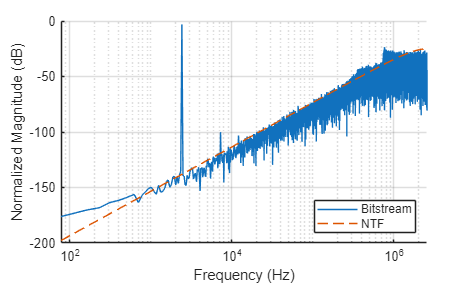

fig = figure('Units','inches','Position',[0 0 5 3]);
fontname(fig,'TeXGyreTermes');
fontsize(fig,10,"points");

f = 1/Ts/N*(0:N/2);
hold on;
% Spectrum of bitstream
plot(f,mag2db(fft_bitstream));
% Theoretical spectrum of quantization noise
plot(f,mag2db(sqrt(1/6/Ts)/N.*abs((1-exp(-1i*2*pi.*f*Ts)).^2)),"LineStyle","--");
hold off;
xscale('log');
xlabel("Frequency (Hz)");
ylabel("Normalized Magnitude (dB)");
legend(["Bitstream", "NTF"],"Location","southeast");
grid on;

exportgraphics(fig,"figures/fft.svg");